## How to draw a apple

- Step 1,using SP function to draw the main part

- Step 2,draw a stem

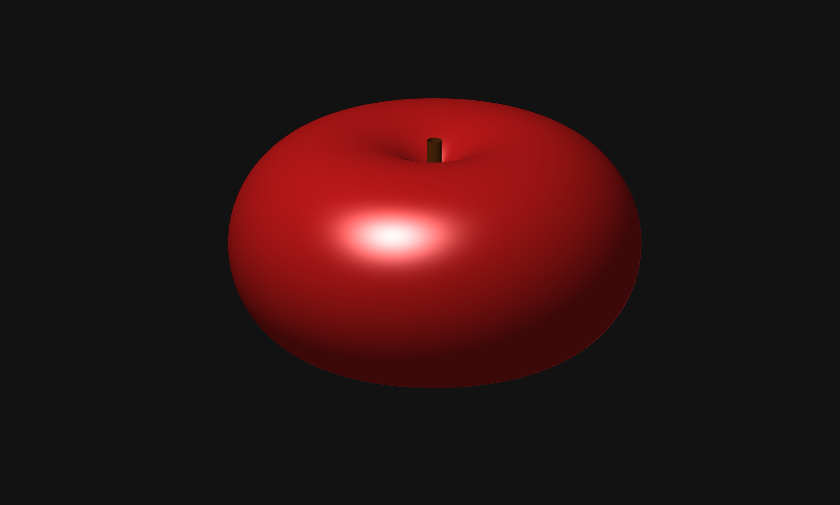

u = linspace(0, 2*pi, 200);
v = linspace(0, 2*pi, 200);
[U, V] = meshgrid(u, v);
a = 1;
r = 1.2;
[X, Y, Z] = SP(U, V, a, r);
figure;
apple_color = [0.8, 0.1, 0.1];
surf(X, Y, Z, 'FaceColor', apple_color, 'EdgeColor', 'none');
hold on;
z_top_dimple = sqrt(r^2 - a^2);
stem_radius = 0.08; 
stem_height = 0.5;  
[stem_X_cyl, stem_Y_cyl, stem_Z_cyl] = cylinder(stem_radius, 20); % 创建一个圆柱体
% 调整圆柱体的位置和大小，作为苹果梗
stem_Z_final = stem_Z_cyl * stem_height + z_top_dimple; % 向上移动到苹果凹陷处
% 定义梗的颜色并绘制
stem_color = [0.4, 0.2, 0.05]; % 定义一个棕色
surf(stem_X_cyl, stem_Y_cyl, stem_Z_final, 'FaceColor', stem_color, 'EdgeColor', 'none');
axis equal;      % 坐标轴等比例，防止苹果被压扁
camlight;        % 添加光源，使表面有光泽
lighting gouraud;% 设置光照模式
view(45, 20);    % 设置观察视角
axis off;        % 关闭坐标轴显示
hold off;        % 结束绘图
grid on;

function [x, y, z] = SP(u, v, a, r)
    x = (a + r*cos(u)).*cos(v);
    y = (a + r*cos(u)).*sin(v);
    z = r*sin(u);
end
